clear; clc; close all

## POSITION CIRCUIT

% Impedance Matching Resistors
Ri1 = 100e3; % Ohm
Ri2 = 12e3; % Ohm

% Desired First Op-Amp Gain
% This was arbitrarily chosen to get nominal values
G1 = 7; % Must be less than or equal to 10

% Max Voltages
V_theta2_max = 350/2; % V
V_pos_max = 5; % V
V_off = -2.5; % V
% Because this is a summing amp and R1 = R2 = Ri1
% so it acts as an inverting amp with V_in_max as input voltage
V_in_max = V_pos_max + V_off; % V

% Solving for Filter Resistor 1
Rf1 = G1*Ri1; % Ohm
V_theta1_max = V_in_max*G1; % V

% Solving for Filter Resistor 2
Rf2 = (V_theta2_max/V_theta1_max)*Ri2; % Ohm
G2 = Rf2/Ri2;

% Returning Values
G1

G1 = 7

G2

G2 = 10


Ri1

Ri1 = 100000

Ri2

Ri2 = 12000


% 680K and 22K in series
Rf1

Rf1 = 700000

Rf2

Rf2 = 120000

## SYSTEM

% Givens
g = 9.81; % m/s/s
L_r = 101.6/1000; % m
m_r = 18.14/1000; % kg
m_b = 32/1000; % kg
r_b = 6.35/1000; % m

% Given Damping Ratio (Zeta) and Settling Time (ts)
zeta = 0.707;
ts = 0.5; % s

% Moments of Inertia
J_b = 1/2 * m_b*r_b^2 % kg.m^2

J_b = 6.4516e-07

J_r = 1/3 * m_r*L_r^2 % kg.m^2

J_r = 6.2417e-05

J_m = 33.5/(1000*100^2) % kg.m^2

J_m = 3.3500e-06

J = J_r + J_b + m_b*(L_r + r_b)^2 + J_m % kg.m^2

J = 4.3931e-04


% Combined Mass
m = (m_b + m_r/2) % kg

m = 0.0411


% Motor Constants
K_e = 1/369 * 30/pi; % V/rad/s
K_t = 25.9/1000; % N.m/A

% The constants are equal to one another so we unify them
K = K_t; % N.m/A

% Motor Values
R = 0.611; % Ohm
L = 0.119/1000; % H
b = 0;

% Calculation of Natural and Damped Natural Frequency
w_n = 4/(zeta*ts); % rad/s
f_n = w_n/(2*pi); % Hz
w_d = w_n*sqrt(1-zeta^2); % rad/s
f_d = w_d/(2*pi); % Hz

% Desired Step Characteristics
M_percent = exp((-zeta*pi)/sqrt(1-zeta^2))*100

M_percent = 4.3255

tp = pi/w_d

tp = 0.3926


% Plant based on Coefficient Matching
ideal_plant = tf(K/J,[1 2*zeta*w_n w_n^2]); % radians

% Derivative of the Plant (Plant = Position; Derivative = Velocity)
s = tf('s');
p_deriv = ideal_plant*s;

% Maximum Velocity of the Plant
max_vel = max(step(p_deriv)) % rad/s

max_vel = 2.3757


% Maximum dVin/dt; Input to Differentiator
dVin_dt_max = max_vel * 180/pi * 5/350 % V/s

dVin_dt_max = 1.9445

% Velocity range is equal to dVin/dt for our model
vel_range = dVin_dt_max;

% Returning Values
f_n

f_n = 1.8009

f_d

f_d = 1.2736

dVin_dt_max

dVin_dt_max = 1.9445

## VELOCITY CIRCUIT

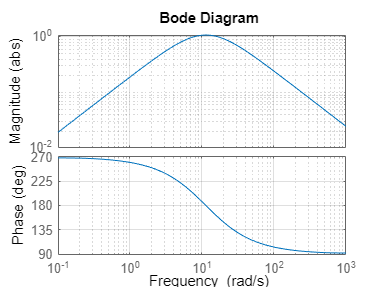

% Cutoff Frequency
w_c = 2*pi*f_n; % rad/s

% Desired Gain and First Capacitor
% Needs to be less than 1
% Chosen to obtain nominal capacitor and resistor values
G = 0.19;  % this is gain (10^0 = 1) @ 1 rad/sec
C1 = 47e-6; % F or 1 pico F

% Calculate Component Values
    % equations from prdiff.m
    % w_c = 1/(C1*R1) = 1/(C2*R2)
    % Gain at 1 rad/sec = C1*R2 / (1 + 1/w_c^2)
R1 = 1/(C1*w_c); % Ohm
R2 = (1/C1)*G*(1+1/w_c^2); % Ohm
C2 = 1/(R2*w_c); % F

% Calculate Transfer Function
num = [ -C1*R2, 0 ];
den = [ C1*C2*R1*R2, (C1*R1) + (C2*R2), 1 ];
sys1 = tf(num,den);

% Plotting Vo/Vi Bode
figure
bode(sys1)
grid on
setoptions(gcr,'MagUnits','abs')
setoptions(gcr,'MagScale','log')

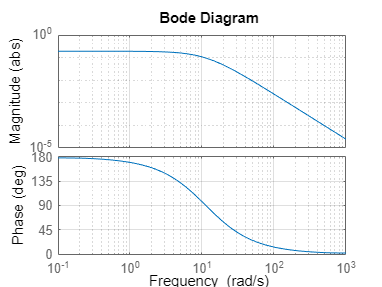


% Plotting Vo/dVin Bode
figure
sys2 = sys1/s;
bode(sys2)
grid on
setoptions(gcr,'MagUnits','abs')
setoptions(gcr,'MagScale','log')


% Gain and Maximum Velocity Calculations
G3 = abs(freqresp(sys1,w_d)) % Must be less than 10

G3 = 1.0215

V_theta_dot1_max = dVin_dt_max*G3 % Must be less than 10

V_theta_dot1_max = 1.9863


% Inverting Op amp
% Required gain to meet 10V requirement
G4 = 10/V_theta_dot1_max;
% Arbitrary Impedance Matching Resistor
Ri3 = 2.4e3; % Ohm
% Calculation of Filter Resistor
Rf3 = G4*Ri3; % Ohm

% Max voltage output of Velocity Circuit
% (Pre Control Gains)
V_theta_dot2_max = G4*V_theta_dot1_max;

% Returning Values
R1

R1 = 1.8803e+03

R2

R2 = 4.0741e+03

C1

C1 = 4.7000e-05

C2

C2 = 2.1692e-05

Ri3

Ri3 = 2400

Rf3

Rf3 = 1.2083e+04

R1_error = 100*abs((2e3 - R1)/2e3)

R1_error = 5.9840

R2_error = 100*abs((4e3 - R2)/4e3)

R2_error = 1.8532

C2_error = 100*abs((22e-6 - C2)/22e-6)

C2_error = 1.4011

Rf3_error = 100*abs((12e3 - Rf3)/12e3)

Rf3_error = 0.6915

V_theta_dot2_max

V_theta_dot2_max = 10

## CONTROLS

% Servo Amp Gain
K_A = 0.3; % A/Vc
% Degree to Radian Conversion Factor
K_deg_rad = 180/pi; % deg/rad
% Velocity Circuit Gain
K_vel = 10/vel_range; % rad/s/V

% Calculation of System Control Gains
K_theta = (J*w_n^2 + m*g*L_r)/K;
K_theta_dot = 2*zeta*w_n*J/K;

% Conversion to Op-Amp Gains
G_theta = K_theta / (K_deg_rad * K_A);

G_theta = 0.2183

G_theta_dot = K_theta_dot / (K_vel * K_A);

G_theta_dot = 0.1759


% Input Resistors
Ri_theta = 10e3;
Ri_theta_dot = 12e3;
Ri_C = 10e3;
Rf_C = Ri_C;

% Filter resistor calculations
Rf_theta = G_theta*Ri_theta

Rf_theta = 2.1830e+03

Rf_theta_dot = G_theta_dot*Ri_theta_dot

Rf_theta_dot = 2.1109e+03


% Max voltage for specific systems
V_theta_max = 10*G_theta

V_theta_max = 2.1830

V_theta_dot_max = V_theta_dot2_max*G_theta_dot

V_theta_dot_max = 1.7591


% Max Output Voltage of Analog Control System
V_com = (V_theta_max + V_theta_dot_max);

% Returning Values
K_theta

K_theta = 3.7523

G_theta

G_theta = 0.2183

K_theta_dot

K_theta_dot = 0.2714

G_theta_dot

G_theta_dot = 0.1759

Ri_theta

Ri_theta = 10000

Ri_theta_dot

Ri_theta_dot = 12000

Rf_theta

Rf_theta = 2.1830e+03

Rf_theta_dot

Rf_theta_dot = 2.1109e+03

Rf_theta_error = 100*abs((2.2e3 - Rf_theta)/2.2e3)

Rf_theta_error = 0.7738

Rf_theta_dot_error = 100*abs((2.1e3 - Rf_theta_dot)/2.1e3)

Rf_theta_dot_error = 0.5207

V_com

V_com = 3.9421